# 1 DoF controller

close all
clear
clc

Let's define our 1dof control architecture

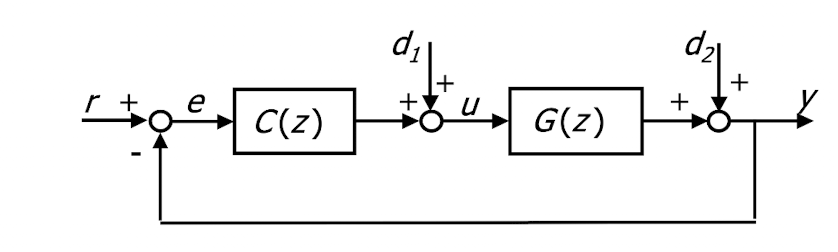

it is made by

- a plant G

- a controller C

- (a unitary feedback loop)

- 3 "input" r, d1, d2

- 3 "output" e, u, y

## Stability and responses

In order to analyze stability and performances of 1dof controller, we need to compute the transfer functions (tf) between every input and every output

### Responses

#### Effect of inputs on y

Since the system is linear, we can do superposition

Effect of r on y


$$Y(z) = \frac{G(z)C(z)}{1+ C(z)G(z)} R(z) \rightarrow W(z) = \frac{G(z)C(z)}{1+ C(z)G(z)} $$


Effect of d1 on y


$$Y(z) = \frac{G(z)}{1+ C(z)G(z)} D_1(z) \rightarrow W_1(z) = \frac{G(z)}{1+ C(z)G(z)} $$


Effect of d2 on y


$$Y(z) = \frac{1}{1+ C(z)G(z)} D_2(z) \rightarrow W_2(z) = \frac{1}{1+ C(z)G(z)} $$


Putting all together:


$$Y(z) = W(z) R(z) + W_1(z) D_1(z) + W_2(z) D_2(z)$$


#### Effect of inputs on e and u

We can do the same procedure with the other 2 outputs

We conclude that:


$$E(z) = W_2(z) R(z) - W_1(z) D_1(z) - W_2(z) D_2(z)   \\

U(z) = W_3(z) R(z) + W_2(z) D_1(z) - W_3(z) D_1(z) \\

\text{with} \quad W_3 = \frac{C(z)}{1+C(z)G(z)}$$


### Stability

In the previous section we have defined 4 tf: W, W1, W2, W3

Now we'll study stability starting from them

**Note: **we'll consider only well-posed feedback system, i.e.

- G(z) strictly proper

- C(z) proper or strictly proper

- (=> all the other tf (W,...) are proper)

**DEF: **a well-posed feedback system is **stable **if all the tf W, W1, W2, W3 are **BIBO stable**

Practically, we have stability if:

- there aren't instable z-p cancellations when the product L(z) = C(z)G(z)  is formed

- all the poles of the tf (i.e. the roots of the denominators) have magnitude **strictly less than one!!**

Moreover, if conditions are met we can **use just one of the four tf to analyze stability!!**

## **Exercises on stability and responses**

**Lab 1, problem 1**

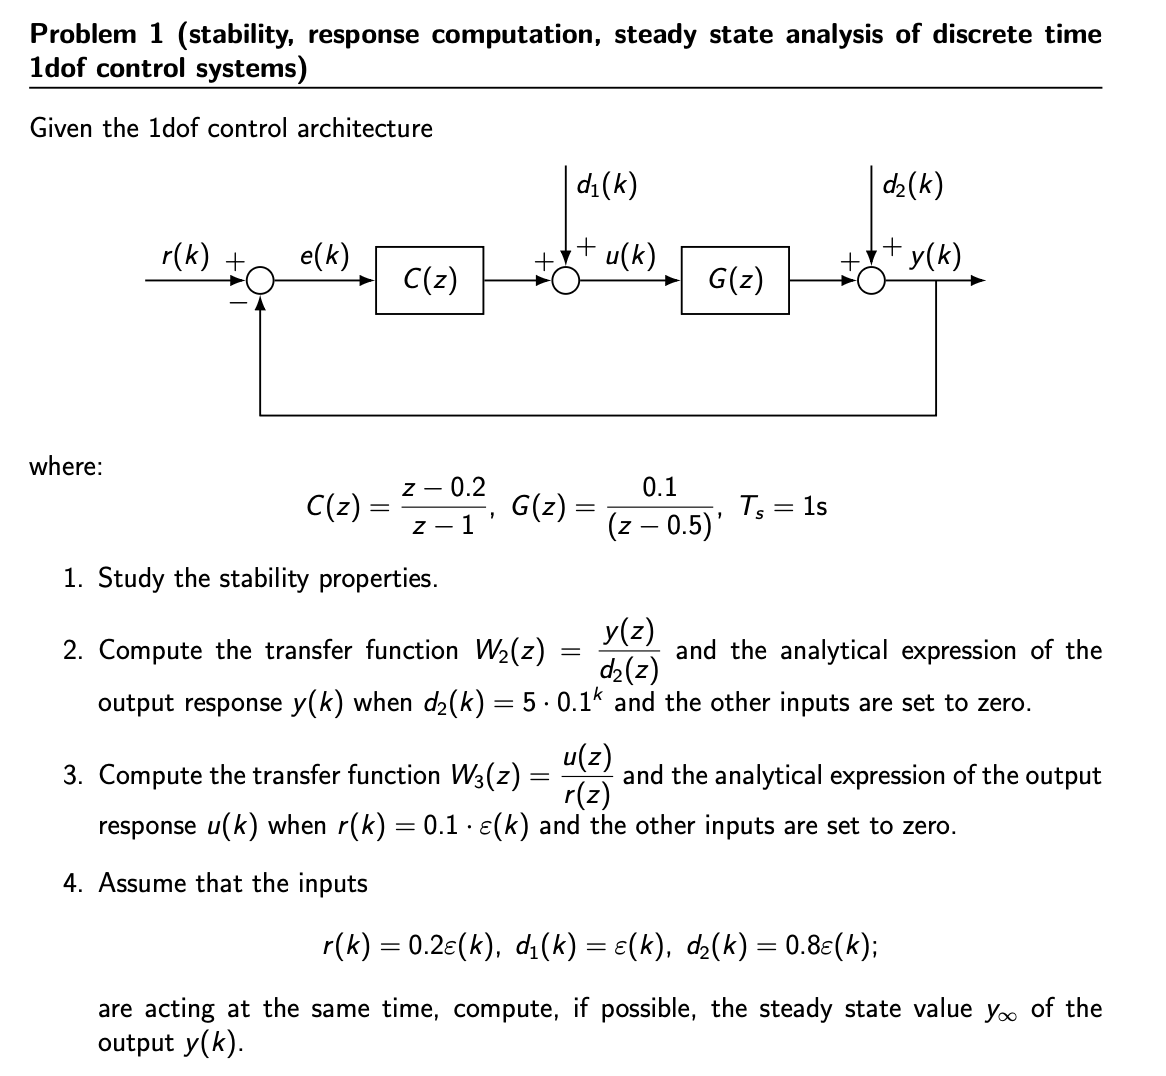

T = 1;
z = tf('z', T);
C = (z-0.2)/(z-1);
G = 0.1/(z-0.5);
L = C*G


L =
 
    0.1 z - 0.02
  -----------------
  z^2 - 1.5 z + 0.5
 
Sample time: 1 seconds
Discrete-time transfer function.


% stability
W2 = zpk(minreal(1/(1+L),1e-2))


W2 =
 
   (z-1) (z-0.5)
  ---------------
  (z-0.8) (z-0.6)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


% we see that all the poles of W2 are < 1 => system is stable

% output response y(d2)
d2 = 5*z/(z-0.1);
Y_d2 = zpk(minreal(W2*d2,1e-2));
[nY_d2, dY_d2] = tfdata(Y_d2, 'v');
[rY_d2, pY_d2, kY_d2] = residuez(nY_d2, dY_d2)

rY_d2 =    -2.1429
    2.0000
    5.1429


pY_d2 =     0.8000
    0.6000
    0.1000


kY_d2 = 0


% output response u(r)
W3 = zpk(minreal(C/(1+L), 1e-2));
r = 0.1*z/(z-1);
U_r = W3*r


U_r =
 
  0.1 z (z-0.5) (z-0.2)
  ---------------------
  (z-0.8) (z-1) (z-0.6)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


[nU_r, dU_r] = tfdata(U_r, 'v');
[rU_r, pU_r, kU_r] = residuez(nU_r, dU_r)

rU_r =     0.5000
   -0.4500
    0.0500


pU_r =     1.0000
    0.8000
    0.6000


kU_r = 0


% output response & steady state
r = 0.2*z/(z-1);
d1 = z/(z-1);
d2 = 0.8*z/(z-1);

W = zpk(minreal(L/(1+L), 1e-2));
W1 = zpk(minreal(G/(1+L), 1e-2));

Y = zpk(minreal(W*r + W1*d1 + W2*d2, 1e-2))


Y =
 
  0.8 z (z-0.3824) (z-0.9676)
  ---------------------------
     (z-0.8) (z-1) (z-0.6)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



y_inf = dcgain(minreal((z-1)*Y, 1e-2)) % steady state

y_inf = 0.2000

## Steady State Analysis

We are often asked of satisfy some requirements when all the transitions are dead (ie t-> inf), wrt polynomial signals

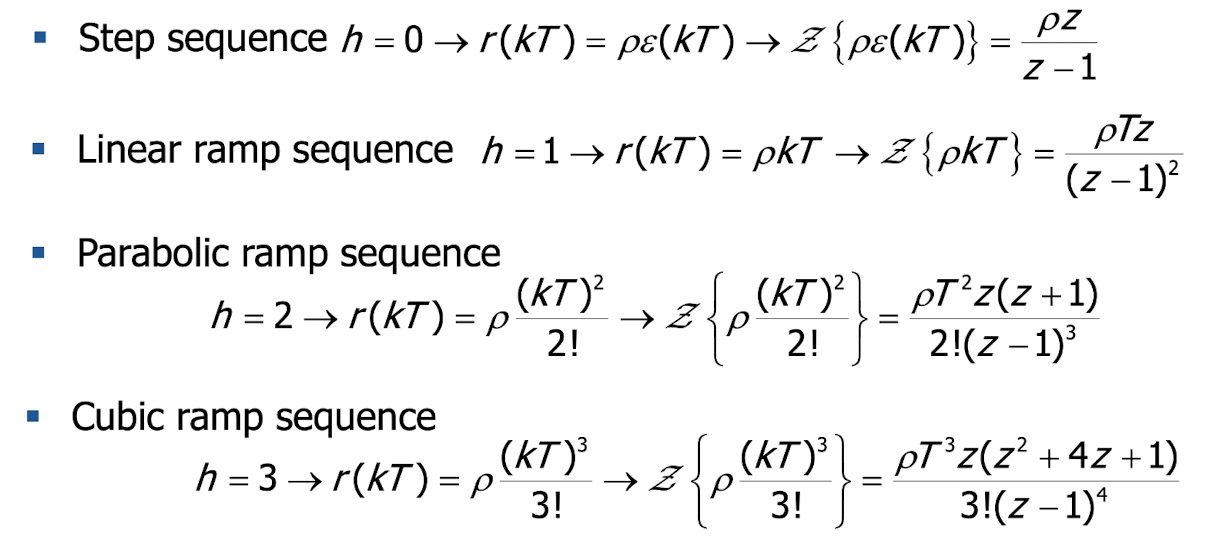

**Note: **(rho (or delta1/delta2) is the amplitude

These requirements define the number of pole in z=1 of our controller. Moreover, it can occur that we have to add an extra equation in the sylvester matrix to account steady state constraints (see below) 

Nothing else special to say, just see the tables and satisfy requirements. Remember that we have to consider just the strictest 

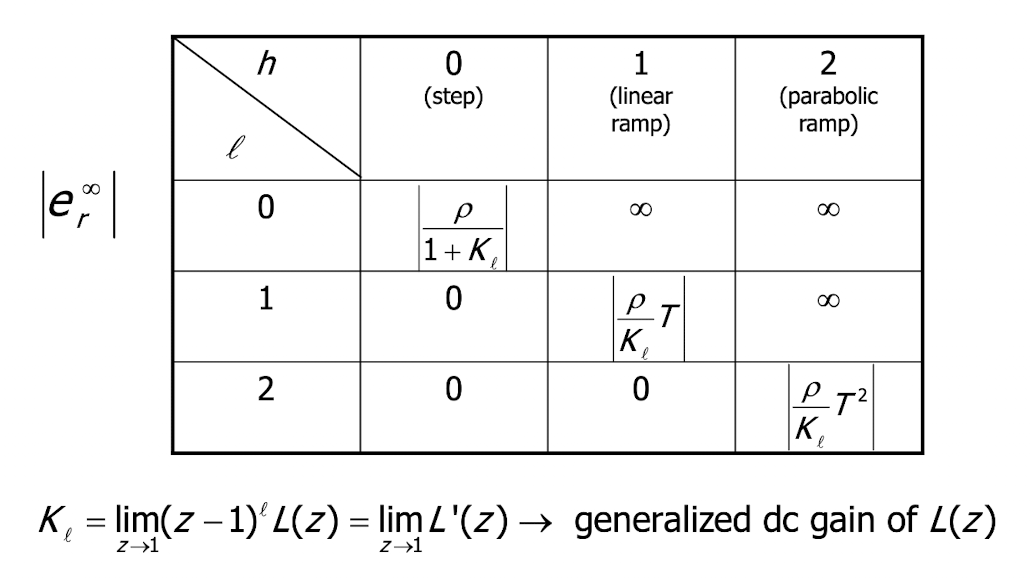

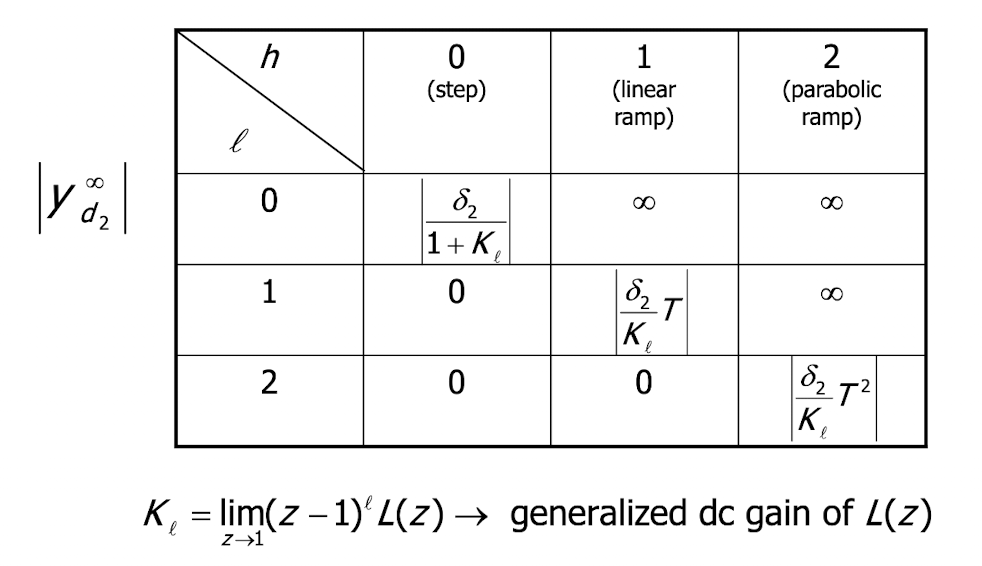

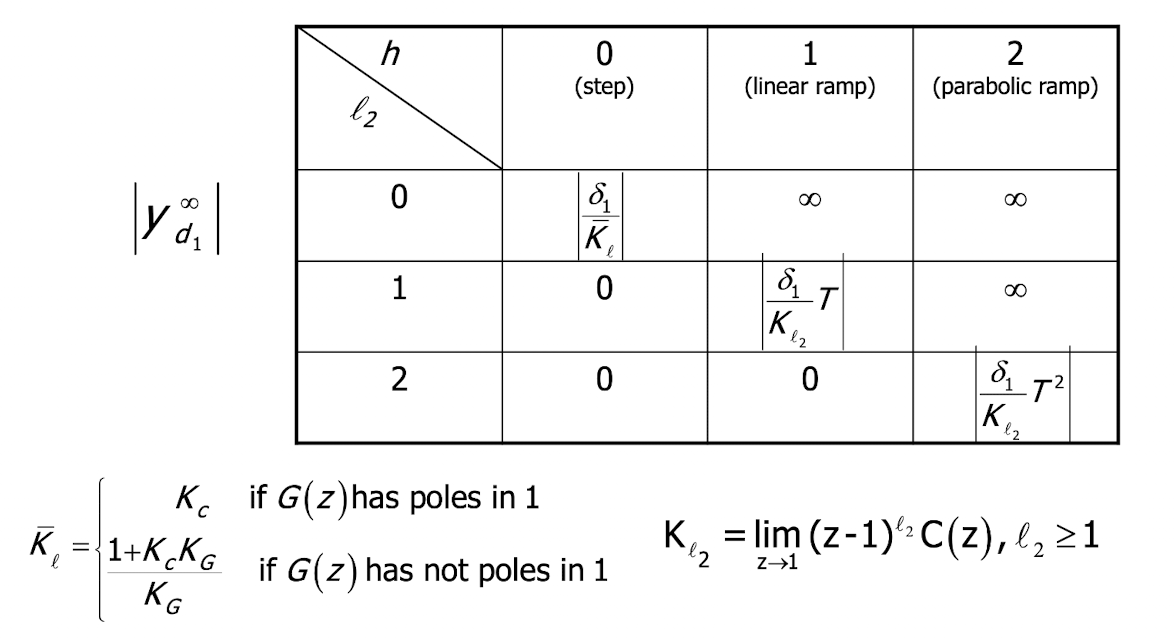

## Pole Placement Control

Before starting, let's define our quantities C,G,W:


$$C(z) = \frac{S(z)}{R(z)} \\
G(z) = \frac{B(z)}{A(z)}$$


Then we can also explicit the roots in 1, thus obtaining:

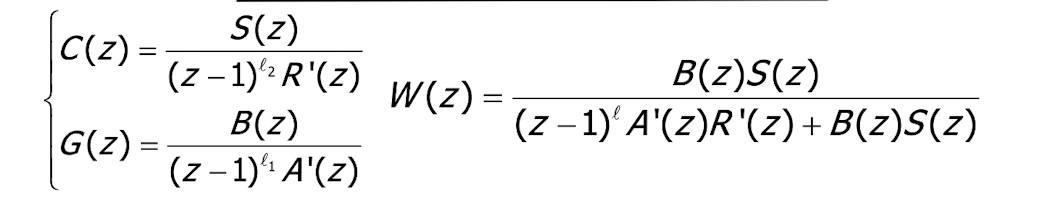

and let's assume that:

- A(z) and B(z) are coprime -> no common roots

- G(z) is strictly proper -> deg(A(z)) > deg(B(z))

- A(z) is monic -> the term with higher exponent has unitary coefficient

- B(z) hasn't roots in z = 1

- C(z) is proper -> deg(R(z)) >= deg(S(z))

Now we can start...

Pole placement is a control technique that allows us to design a controller C(z) to place the roots of the closed loop characteristic polynomial (i.e. the denominator of W) at given arbitrary locations described by a known polynomial Am

So our aim is to compute the unknown polynomials S(z) and R'(z), i.e. "some parameters" of our controller. We do it by solving a **diophantine equation**

#### What is the degree of these unk polynomials and Am? -> formulary

#### How can we choose poles?

Closed loop poles are chosen based on transient requirements of the feedback system. The following parameters are used to define the transient performance:

- Max overshoot -> accuracy

- Rise time -> trigger off quickness

- Settling time -> extinction quickness

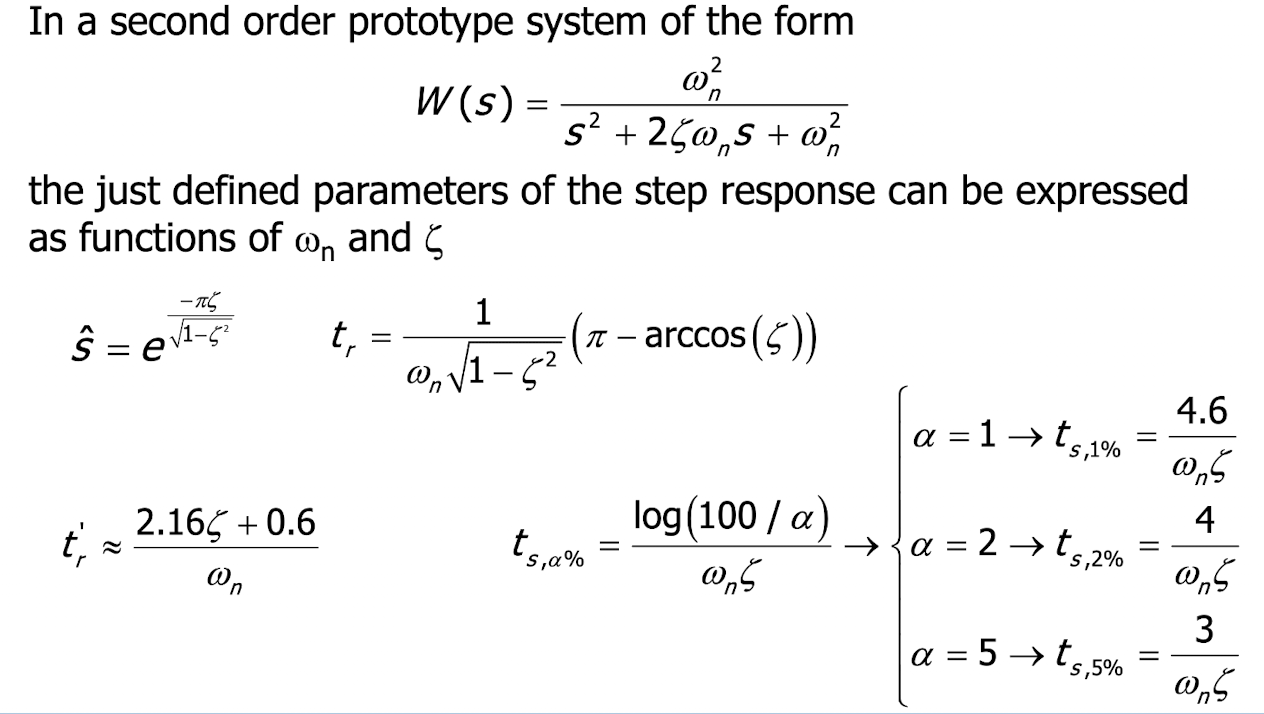

**Note: **in exercises we'll use overshoot and settling time expressions

Since we spoke about a second order prototype, these formula allow us to choose just 2 poles! In we have more than 2 poles => we choose coincident real poles that have a faster dynamics wrt complex conj poles

### Complete controller - z-p cancellations and extra eq

#### z-p cancellations

To simplify the main closed loop dynamics, stable z-p cancellatoins between G and C can be imposed. In theory, we can cancel every stable roots, but practically **we'll cancel just the roots that are in the cardioid  **

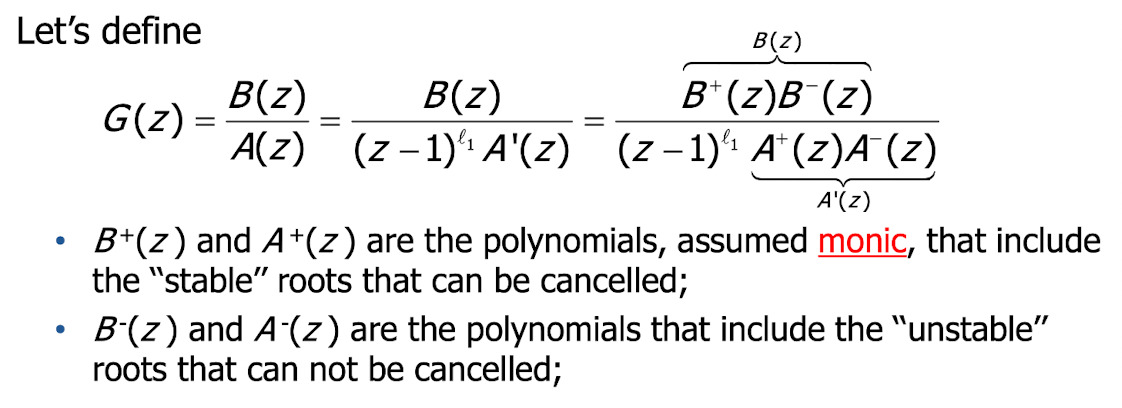

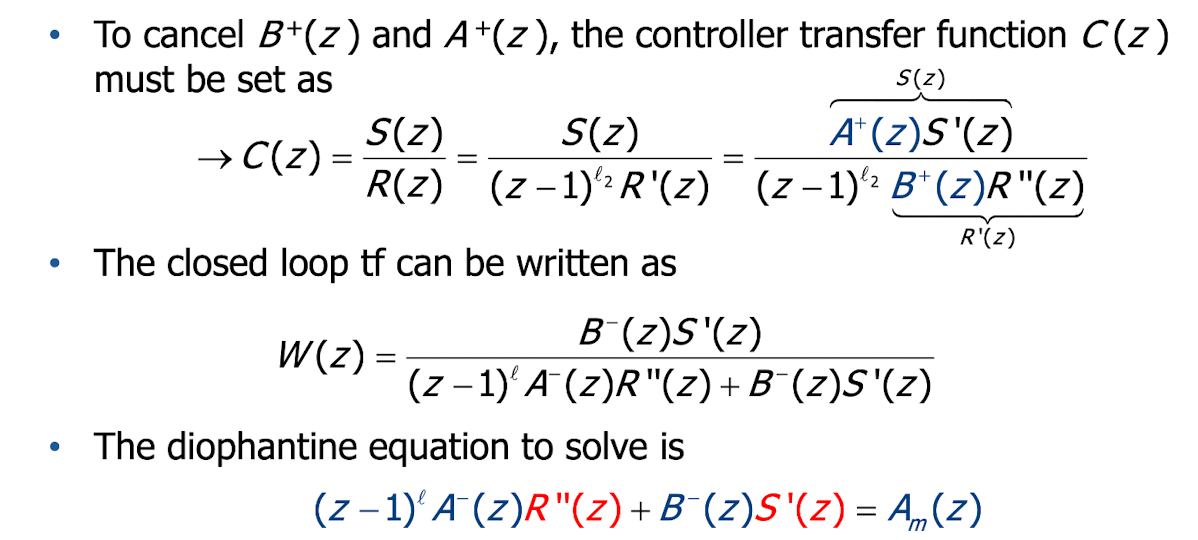

#### **Extra equation**

S.s. requirements often imposes an additional condition on the coefficients of the controller transfer function => we will have an extra row in the sylvester matrix, in which the coefficients of this extra eq are present (see example). Degrees of polynomials in dioph eq will increase.

## Exercise 1DoF controller

**Lab 2, problem 1**

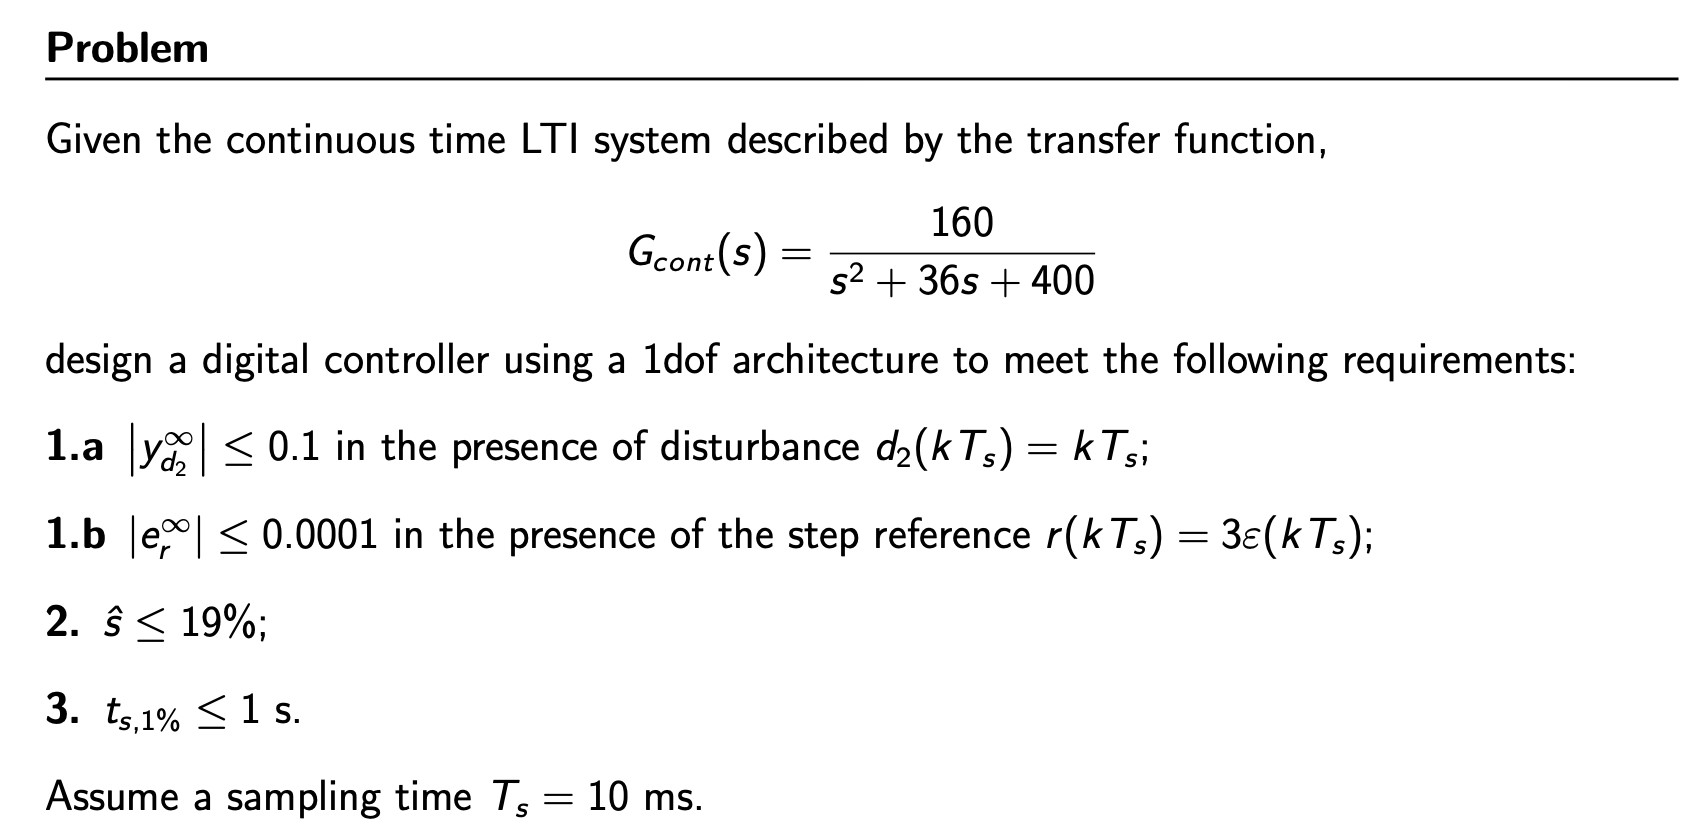

clear

Ts = 10e-3;
s = tf('s');
z = tf('z',Ts);
G_cont = 160/(s^2 + 36*s + 400);

G = c2d(G_cont,Ts, 'zoh');
[zG, pG, kG] = zpkdata(G, 'v')

zG = -0.8869

pG =    0.8321 + 0.0727i
   0.8321 - 0.0727i


kG = 0.0071

A = conv([1 -pG(1)], [1 -pG(2)]);
B = kG*[1 -zG];

#### Step 1: ss analysis

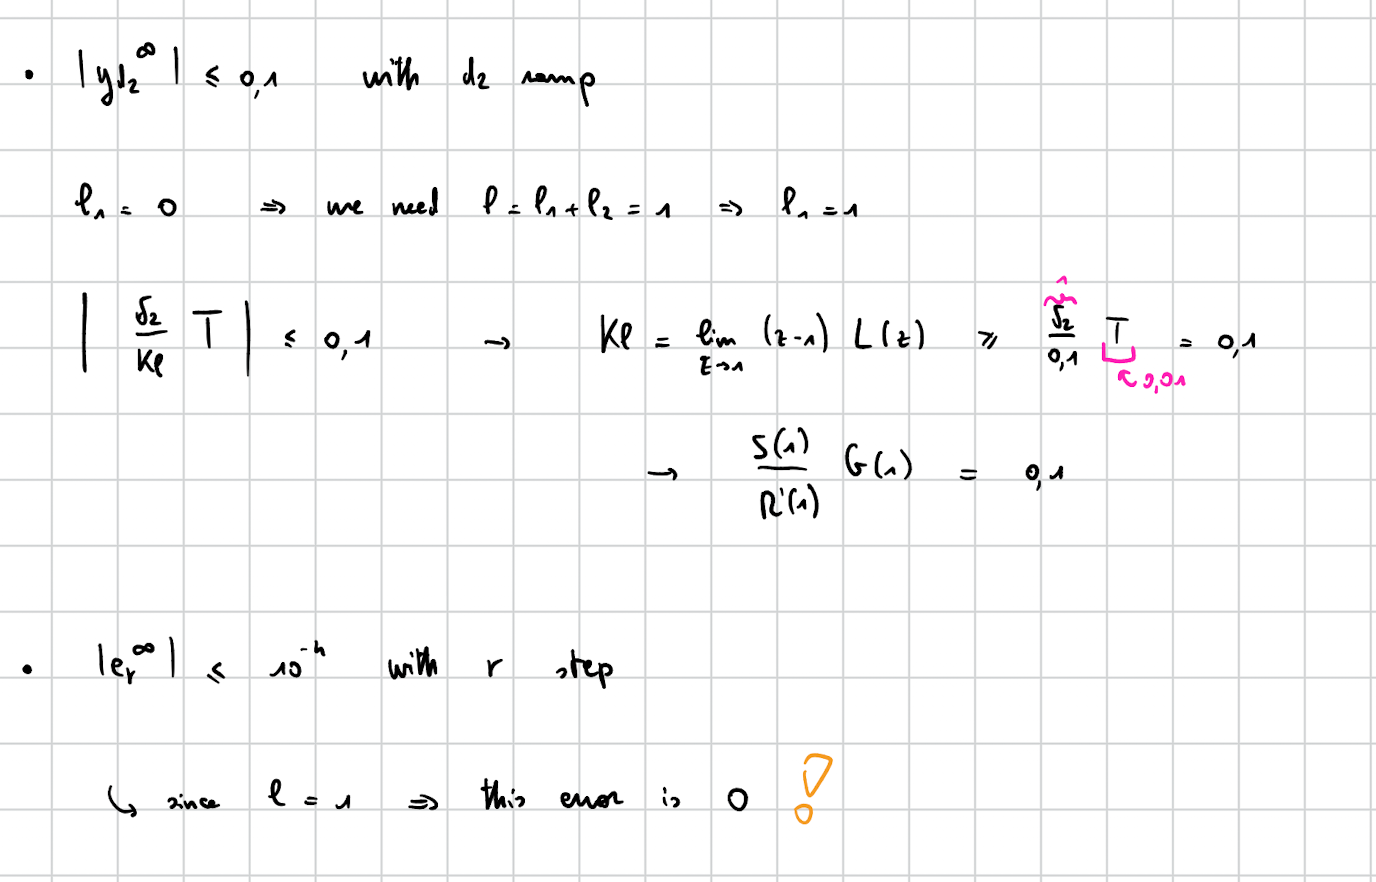

l1 = 0;
l2 = 1;
l = l1 + l2;
n_add = 1;

#### Step 2: transient response

s_hat = 0.19;
t_s = 1;

zeta = abs(log(s_hat))/(sqrt(pi^2 + log(s_hat)^2)) % formulary

zeta = 0.4673

wn = 4.6/(t_s*zeta) % formulary

wn = 9.8428


% let's plot the corresponding cardioid
% figure
% pzmap(G, 'r')
% hold on
% zgrid(zeta,wn, Ts)
% axis('equal')

#### Step 3: z-p cancellations 

from the plot we can see that we can cancel both poles

A_plus = A; % we want to cancel all the denominator
A_minus = 1; 
B_plus = 1;
B_minus = B;

% note: this is an easy case since matrices are either an already 
% defined matrix (A,B) or 1.
% it can happen that we have to "create" new matrix
% in order to do so, we use vector format and convolution 
% here an example of (z-p1)(z-p2)
% A_ex = conv([1 -p1], [1 -p2])

#### Step 4: analyzing degrees of polynomials

Now let's focus on degree (formulary)

deg_A = 2;
deg_A_minus = 0;
deg_A1 = deg_A; % G has not poles in 1
deg_B_plus = 0;

deg_S1 = l + deg_A_minus - 1 + n_add

deg_S1 = 1

deg_R2 = deg_A1 - deg_B_plus + l1 - 1 + n_add

deg_R2 = 2

deg_Am = l + deg_A1 + deg_A_minus + l1 - deg_B_plus - 1 + n_add

deg_Am = 3

#### Step 5: define poles 

Since deg(Am) = 3 => we need 3 poles

As previously told, we will have 2 complex conj poles and 1 real pole

p1c = - zeta*wn + 1j*wn*sqrt(1-zeta^2); % formula (NOT IN FORMULARY)
p1 = exp(p1c*Ts); % sampling transformation -> I get the pole value in DT

p2c = - zeta*wn - 1j*wn*sqrt(1-zeta^2);
p2 = exp(Ts*p2c);

p3c = - 5*zeta*wn;
p3 = exp(Ts*p3c);


#### Step 6: solve dioph eq

Now we have to solve diophantine equation. If we use matrix representation, we have to solve the linear system $M_s \Theta = \Gamma$ where Ms is the Sylvester matrix (to see how it's built check the slides); $\Theta
$ is the vector containing all the unknowns (in our case, 3 coeff for R'' and 2 coeff for S'); $\Gamma$ is the vector containing Am coeff and a 0 at the end to account for the extra condition

Am = poly([p1 p2 p3])

Am =     1.0000   -2.6974    2.4240   -0.7247



A_dioph = conv([1 -1], A_minus) % A_minus = 1

A_dioph =      1    -1


B_dioph = B_minus

B_dioph =     0.0071    0.0063



% extra condition coeff
B_plus_1 = polyval(B_plus, 1);
A_plus_1 = polyval(A_plus, 1);
G_1 = dcgain(G);
extra_eq = [0.1*B_plus_1*ones(1,3) -A_plus_1*G_1*ones(1,2)];

extra_eq =     0.1000    0.1000    0.1000   -0.0134   -0.0134



% now let's solve dioph eq
Gamma = [Am(:); 0];
Ms = zeros(length(Gamma));

Ms =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


Ms = [[[A_dioph(:); 0; 0], [0; A_dioph(:); 0], [0; 0; A_dioph(:)] ...
    [0; B_dioph(:); 0], [0; 0; B_dioph(:)]]; ...
    extra_eq];

Ms =     1.0000         0         0         0         0
   -1.0000    1.0000         0    0.0071         0
         0   -1.0000    1.0000    0.0063    0.0071
         0         0   -1.0000         0    0.0063
    0.1000    0.1000    0.1000   -0.0134   -0.0134



Teta = Ms\Gamma;

% now we have to split Teta into R'' coeff and S' coeff
R2 = Teta(1:deg_R2+1);
S1 = Teta(deg_R2+2:end);

#### Step 7: build controller

Finally, we can build our controller 

R = conv([1 -1], conv(B_plus, R2));

R =     1.0000
   -2.7023
    2.4235
   -0.7213


S = conv(A_plus, S1);

S =     0.6869   -1.6881    1.3862   -0.3802



C = zpk(tf(S(:)',R(:)',Ts));


C =
 
  0.68688 (z-0.7934) (z^2 - 1.664z + 0.6977)
  ------------------------------------------
         (z-1) (z-0.9073) (z-0.7949)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.


#### Simulation

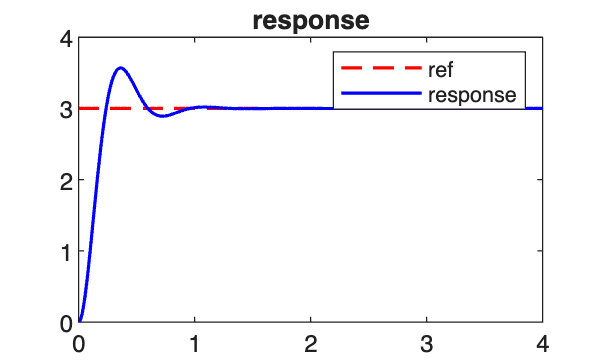

Tend = 4;
rho = 3;
delta_2 = 0;

out = sim("OneDoF_simulation.slx");
r = out.r;
y = out.y;

figure
plot(r.time, r.data, 'r--', linewidth=1.2)
hold on
plot(y.time, y.data, 'b', linewidth=1.2)
title("response")
legend("ref","response")

We can see that ss tracking error requirement and transient response requirements are satisfied. In case if transient response requirements were not met => we could act on zeta and wn expression. In particular, we could add a multiplication coeff to the damping in order to have a damped response

Let's verify also ss requirements of d2 disturb

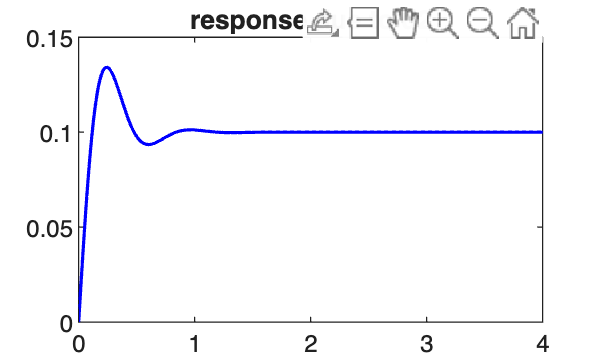

rho = 0;
delta_2 = 1;
clear out 
out = sim("OneDoF_simulation.slx");
y = out.y;

figure
plot(y.time, y.data, 'b', linewidth=1.2)
title("response due to d2")

we can see from the plot that also this requirement is met